# Visualize Net Loss Landscape

rng(0)

## Load trained net

net = load("ImitationLearningSimulink\ActualArchitecture\net.mat").net;

## Create random net

argsFFNN                  = struct();
argsFFNN.Ninputs          = Ninputs;
argsFFNN.Noutputs         = Noutputs;
argsFFNN.Nlayers          = 3;
argsFFNN.Nneurons         = 5*Ninputs;
argsFFNN.HiddenActivation = 'relu'; % relu, tanh, sigmoid
argsFFNN.OutputActivation = 'tanh';
argsFFNN.Dropout          = 0;
argsFFNN.WinitFcn         = 'glorot';
argsFFNN.BinitFcn         = 'narrow-normal';
argsFFNN.BatchNorm        = false;
argsFFNN.TrainBias        = true;

net = dlupdate(@double, FFNNgenerator(argsFFNN));
for i = 1:numel(net.Learnables.Value)
    net.Learnables.Value{i} = dlarray(randn(size(net.Learnables.Value{i})));
end

## Loss Specifications

output_variance = var(extractdata(dlY_tr), 0, 2);
var_e = mean(output_variance(1:n));
var_o = output_variance(end);
ErrorWeights = [ones(n, 1)*var_o/var_e; 1];

argsFFNNtrain.HuberThreshold = 1;
argsFFNNtrain.ErrorWeights = ErrorWeights;

## Create random directions for each parameter

learnables0 = net.Learnables.Value;
Nparams = numel(learnables0);
D1 = {};
D2 = {};
for i = 1:Nparams
    learnables = extractdata(learnables0{i});
    % Create directions
    d1 = randn(size(learnables));
    d2 = randn(size(learnables));
    % Bias
    if isvector(learnables)
        norm_w = norm(learnables(:));
        norm_d1 = norm(d1(:));
        norm_d2 = norm(d2(:));
        
        D1{i} = d1 * (norm_w / (norm_d1 + eps));
        D2{i} = d2 * (norm_w / (norm_d2 + eps));
    % Weights
    else
        % Row-wise norm
        norms_W = vecnorm(learnables, 2, 2); 
        norms_d1 = vecnorm(d1, 2, 2);
        norms_d2 = vecnorm(d2, 2, 2);
        
        D1{i} = d1 .* (norms_W ./ (norms_d1 + eps));
        D2{i} = d2 .* (norms_W ./ (norms_d2 + eps));
    end
end

## Calculate loss in 1 direction

res = 100;
h = waitbar(0, 'Calculating Loss...');
iter = 0;
w_vec = linspace(-1, 1, res) * 2;
Performance_tr = zeros(res, 1);
Performance_val = zeros(res, 1);
for i = 1:res
        for k = 1:Nparams
            learnables = extractdata(learnables0{k});
            learnables = learnables + D1{k} * w_vec(i);
            net.Learnables.Value{k} = dlarray(learnables);
        end
        Performance_tr(i) = extractdata(dlfeval(@FFNNLoss, net, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights));
        Performance_val(i) = extractdata(dlfeval(@FFNNLoss, net, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights));
        iter = iter + 1;
        waitbar(iter/res, h, sprintf('Calculating Loss: %d%%', round(100*iter/res)));
end
close(h)

## 2D Plot

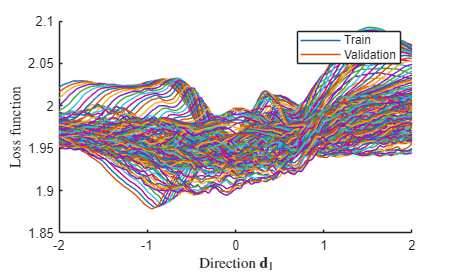

figure('Color', 'w')
hold on
plot(w_vec, Performance_tr);
plot(w_vec, Performance_val);
hold off
legend('Train', 'Validation')
xlabel('Direction $\mathbf{d}_1$', 'Interpreter', 'latex')
ylabel('Loss function', 'Interpreter', 'latex')

## Calculate loss in 2 directions

res = 100;
h = waitbar(0, 'Calculating Loss...');
iter = 0;
w_vec = linspace(-1, 1, res) * 2;
Performance_tr = zeros(res);
Performance_val = zeros(res);
for i = 1:res
    for j = 1:res
        for k = 1:Nparams
            learnables = extractdata(learnables0{k});
            learnables = learnables + D1{k} * w_vec(i) + D2{k} * w_vec(j);
            net.Learnables.Value{k} = dlarray(learnables);
        end
        Performance_tr(i, j) = extractdata(dlfeval(@FFNNLoss, net, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights));
        Performance_val(i, j) = extractdata(dlfeval(@FFNNLoss, net, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights));
        iter = iter + 1;
        waitbar(iter/res^2, h, sprintf('Calculating Loss: %d%%', round(100*iter/res^2)));
    end
end
close(h)

## 3D Plot

Train

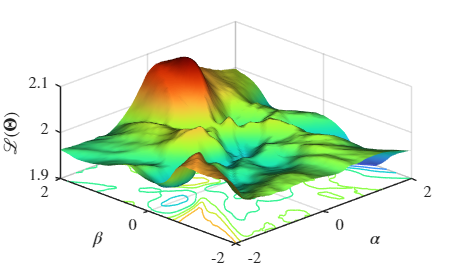

figure('Color', 'w')
s = surfc(w_vec, w_vec, Performance_tr);
s(1).EdgeColor = 'none';       % No grid
s(1).FaceColor = 'interp';     % Interpolate surface
camlight('headlight');      % Light source from camera
lighting gouraud;           % Illumination algorithm
material dull;              % Surface material
colormap(turbo);
view(-45, 45);
xlabel('$\alpha$', 'Interpreter', 'latex', 'Position', [0, -3, 1.9])
ylabel('$\beta$', 'Interpreter', 'latex', 'Position', [-3, 0, 1.9])
zlabel('$\mathcal{L}(\mathbf{\Theta})$', 'Interpreter', 'latex')
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 12);
zlim([1.9, 2.1])
exportgraphics(gcf, 'LossLandscape.pdf', 'ContentType', 'image', 'Resolution', 600);

Validation

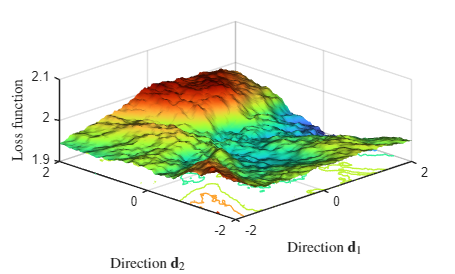

figure('Color', 'w')
s = surfc(w_vec, w_vec, Performance_val);
s(1).EdgeColor = 'none';       % No grid
s(1).FaceColor = 'interp';     % Interpolate surface
camlight('headlight');      % Light source from camera
lighting gouraud;           % Illumination algorithm
material dull;              % Surface material
colormap(turbo);
view(-45, 45);
xlabel('Direction $\mathbf{d}_1$', 'Interpreter', 'latex')
ylabel('Direction $\mathbf{d}_2$', 'Interpreter', 'latex')
zlabel('Loss function', 'Interpreter', 'latex')
zlim([1.9, 2.1])